Suppose we want to find a root of the function 

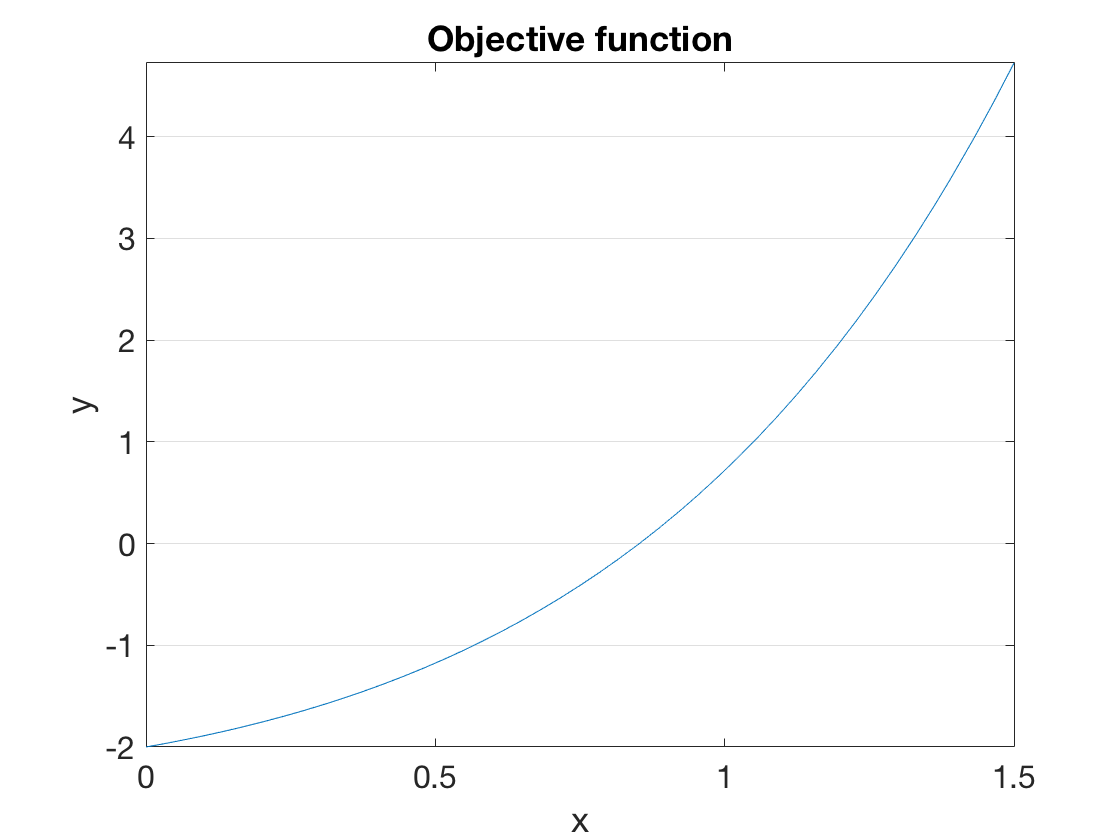

f = @(x) x.*exp(x) - 2;
fplot(f,[0 1.5])
xlabel('x'), ylabel('y')    % ignore this line
set(gca,'ygrid','on')  % ignore this line
title('Objective function')    % ignore this line

From the graph, it is clear that there is a root near $x=1$. So we call that our initial guess, $x_1$.

x1 = 1;
f1 = f(x1)

f1 =    7.1828e-01


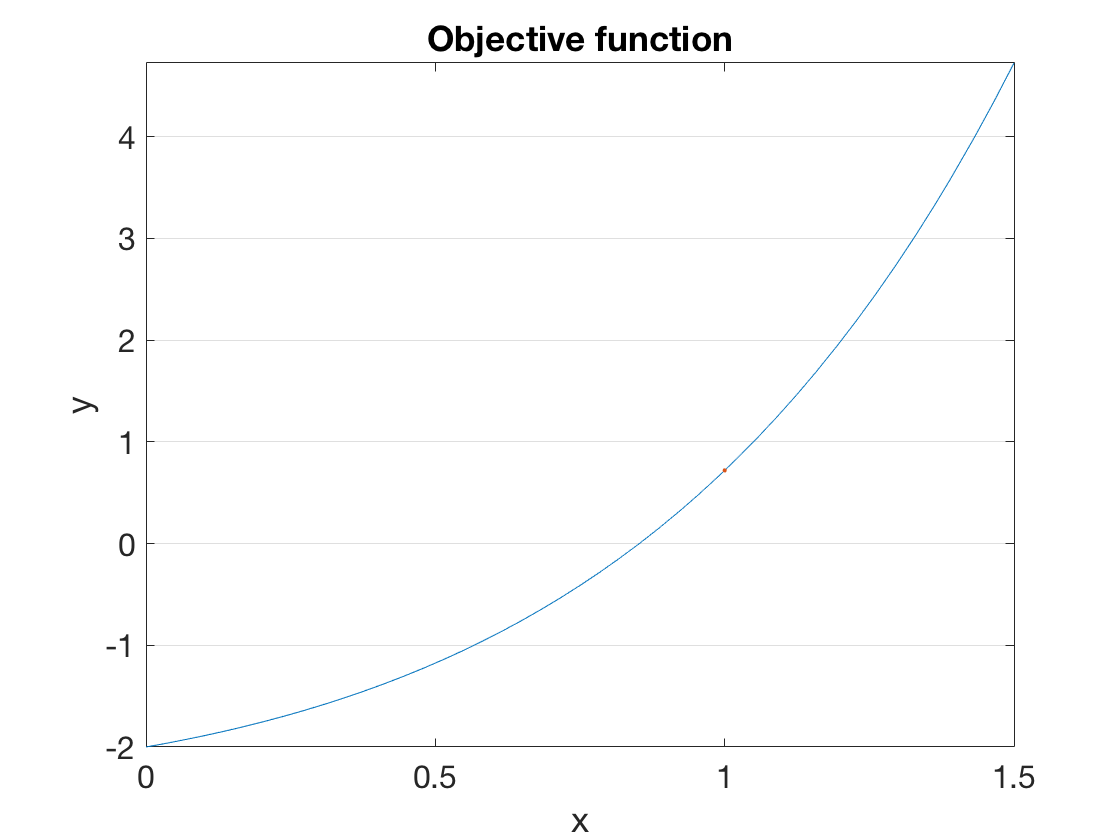

hold on, plot(x1,f1,'.')

Next, we can compute the tangent line at the point $\bigl(x_1,f(x_1)\bigr)$, using the derivative.

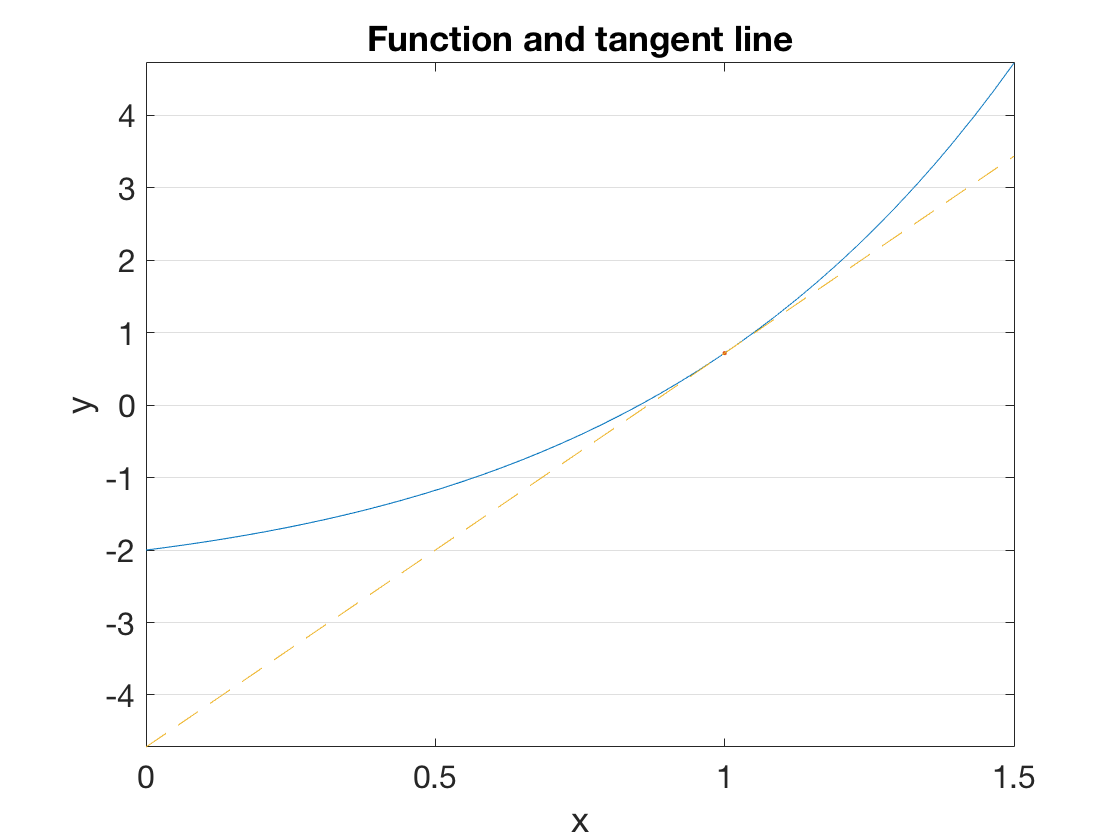

dfdx = @(x) exp(x).*(x+1);
slope1 = dfdx(x1);
tangent1 = @(x) f1 + slope1*(x-x1);
fplot(tangent1,[0 1.5],'--')
title('Function and tangent line')    % ignore this line

In lieu of finding the root of $f$ itself, we settle for finding the root of the tangent line approximation, which is trivial. Call this $x_2$, our next approximation to the root.

x2 = x1 - f1/slope1

x2 =    8.6788e-01


plot(x2,0,'.')
f2 = f(x2)

f2 =    6.7163e-02


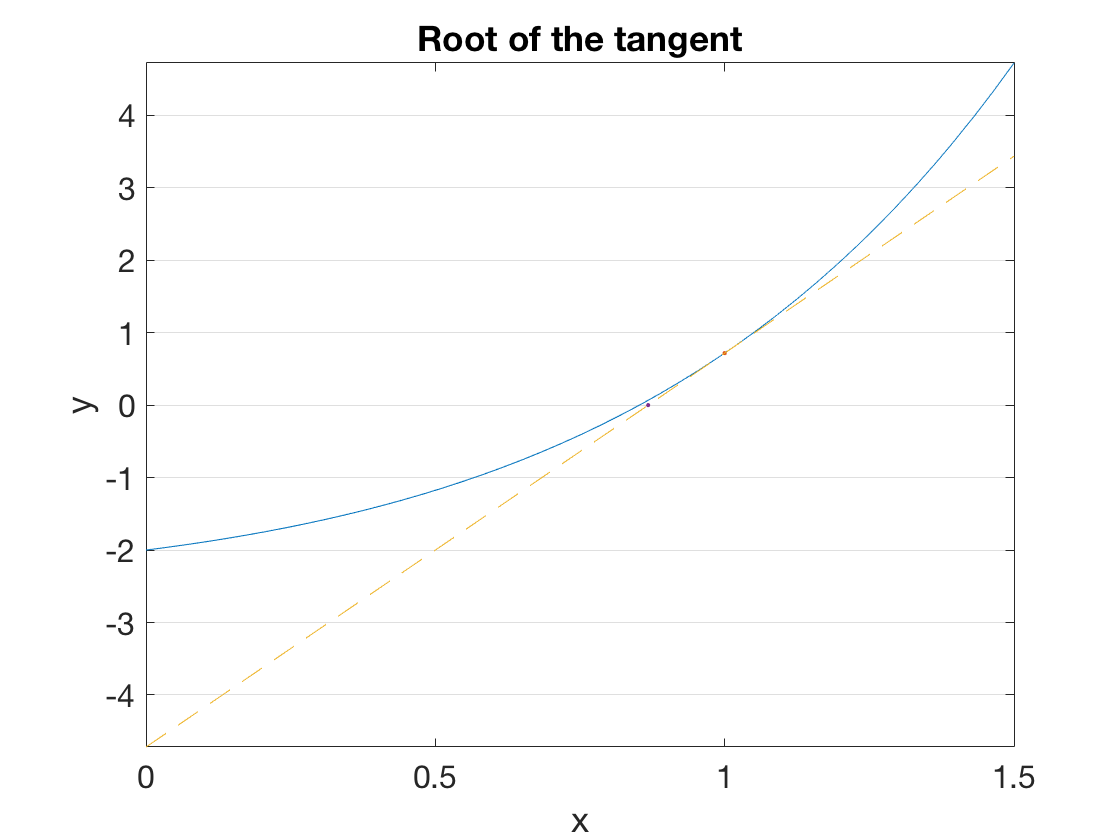

title('Root of the tangent')    % ignore this line

The residual (value of $f$) is smaller than before, but not zero. So we repeat the process with a new tangent line based on the latest point on the curve.

cla, fplot(f,[0.8 0.9])
plot(x2,f2,'.')
slope2 = dfdx(x2);
tangent2 = @(x) f2 + slope2*(x-x2);
fplot(tangent2,[0.8 0.9],'--')
x3 = x2 - f2/slope2;
plot(x3,0,'.')
f3 = f(x3)

f3 =    7.7309e-04


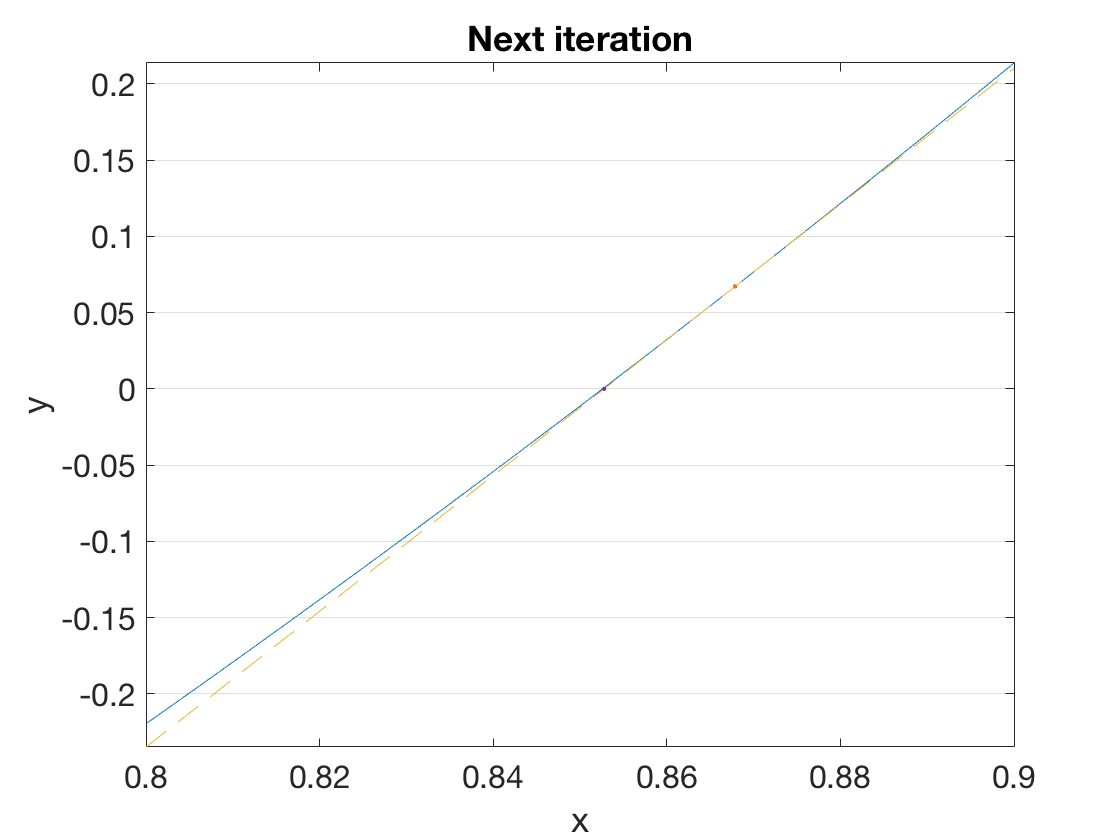

title('Next iteration')    % ignore this line

We appear to be getting closer to the true root each time. 